## Exercise 4

- Please submit answers as code and/or text inside this live notebook

- Code answers will be assessed on both correctness and design.

- You are welcome to work together but all answers should reflect your own understanding and communication.

#### 1. Network construction

**(1.1)** Load the parcellated brain timeseries data [volumetric_timeseries_clean_schaefer.mat](https://brightspace.vanderbilt.edu/d2l/le/content/319368/viewContent/2043766/View) from Brightspace. Use the 100-parcel timeseries and x, y, z coordinates for the following exerices.

data = load("volumetric_timeseries_clean_schaefer.mat");
data = data.Timeseries{1};

**(1.2)** Construct a correlation network from these timeseries as follows:

- Normalize the timeseries to have zero and unit norm (or unit variance).

- Compute a Pearson correlation matrix on the empirical parcel timeseries.

- Generate 1000 timeseries matrices with shuffled values in columns (Class 7, Example 3).

- Compute correlation matrices for each null timeseries, and build a distribution of null correlations

- Preserve only empirical correlations that have p values < 0.01 (two-tailed tests).

data_norm = data - sum(data,2) / 1200;
data_norm = data_norm ./ sqrt(sum((data_norm.^ 2),2));

data_correlation = corr(data_norm');

data_perm = zeros(100, 100, 1000);
for i = 1:1000
    holder = data_norm;    
    for j = 1:1200
        holder(randperm(100), j) = data_norm(1:100, j);
    end
    data_perm(:, :, i) = abs(corr(holder')) >= abs(data_correlation);
end
data_sig = mean(data_perm, 3);

for i = 1:100
    for j = 1:100
        if data_sig(j,i) < .005 || data_sig(j,i) > .995
            data_correlation(j,i) = data_correlation(j,i);
        else
            data_correlation(j,i) = 0;
        end
    end
end 

clear holder;

**(1.3)** Use the `swarmchart` function to visualize all statistically significant correlatiotion values. Add the following title and subtitles to your chart:

`title("Number of positive values: "+number_of_positive_values)`

`subtitle("Number of negative values: "+number_of_negative_values)`

This should show that almost all nonzero values of the correlation matrix are positive, and only a few are negative.

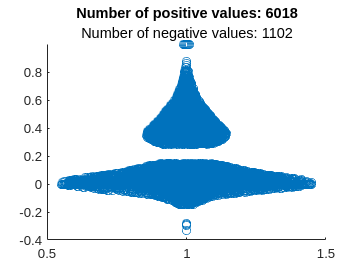

figure;
swarmchart(ones(1,10000), reshape(data_correlation,[],1));
title("Number of positive values: "+sum(reshape(data_correlation,[],1) > 0));
subtitle("Number of negative values: "+sum(reshape(data_correlation,[],1) < 0));

**(1.4)** Set the values of all negative values in your correlation matrix to 0.

data_correlation = max(data_correlation, 0);
min(min(data_correlation)) %check if its less than 0 

ans = 0

#### 2. Module detection: degeneracy

**(2.1)** Use the function `community_louvain` in the Brain Connectivity Toolbox (included in Brightspace). This function finds partitions that optimize the modularity using the Louvain algorithm. Use the default parameters of this function to compute the modular structure of the matrix 100 times with iterative finetuning (as will be discussed in class). Store the partition and the value of the modularity for each run.

k = 100;
paritions = zeros(length(data_correlation), k);
q_score = zeros(1, k);

for i = 1:k
    [paritions(:,i), q_score(i)] = community_louvain_with_finetuning(data_correlation);
end 

**(2.2)** Compute the average partition matrix for all the runs. Elements of this matrix should range from 0 (nodes are never in the same module) to 1 (nodes are always in the same module). You can do this by converting each partition into a binary matrix (where 0 corresponds to pairs of nodes in different module and 1 correspond to pairs of nodes in the same module), and then averaging these matrices.

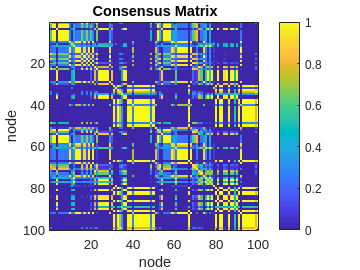

consensus = zeros(size(data_correlation));
for i = 1:k
    parition_consensus = (paritions(:, i) == paritions(:, i)');
    consensus = consensus + parition_consensus;
end
consensus = consensus / k;

figure;
imagesc(consensus);
title("Consensus Matrix")
xlabel('node')
ylabel('node')
colorbar;
axis square

**(2.3)** Visualize a histogram for all (i.e. both zero and nonzero) values of the within-module probability matrix.

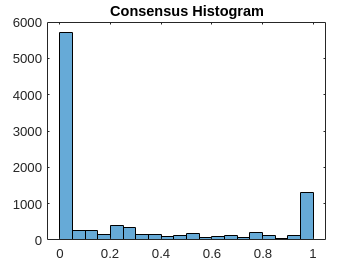

figure;
histogram(consensus);
title("Consensus Histogram")

**(2.4)** Use the function `reorder_mod` in the Brain Connectivity Toolbox to get an order of the indices of the within-module probability matrix that emphasizes its module structure. Visualize the reordered matrix.

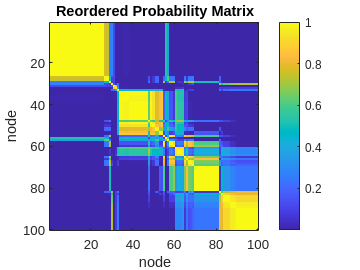

[On, Wr]= reorder_mod(consensus, paritions(:,end));
figure;
imagesc(Wr);
xlabel('node')
ylabel('node')
title("Reordered Probability Matrix")
colorbar;
axis square

**(2.5)** Visualize the histograms of the total number of modules detected in each run.

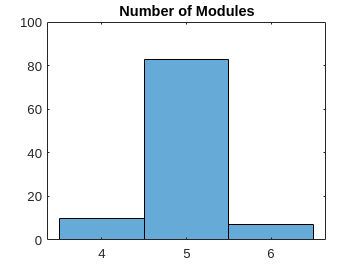

number_of_modules = [];
for i = 1:100
    current_run = paritions(:,i);
    number_of_modules = [number_of_modules, max(current_run)];
end

figure;
histogram(number_of_modules)
title("Number of Modules")

clear current_run

**(2.6)** Visualize the histograms of the values of modularity detected in each run.

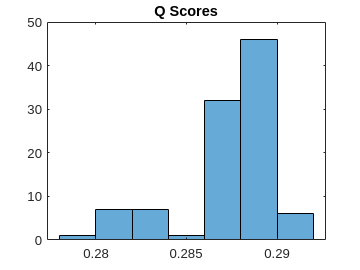

figure;
histogram(q_score)
title("Q Scores")

**(2.7)** Interpret the organization, stability and degeneracy of module partitions using results in **(2.2**-**2.6)**

For 2.2 it appears that the matrix is either very stable or does not agree at all. In other words most of the colors we see are the yellows which represent high agreement or the blues which represent no agreement which the vast majority being a zero. This leads in perfectly to 2.3 the histogram because we see very similar results here as well. The histogram is easier to read in this case and it clearly shows that zero and one are dominate. This means the nodes are either in the same module everytime or never in the same module. It also appears that we have a fairly blockly structure to the matrix based on the reorded probability matrix. We also see that we tend to have the same number of modules as well as similar q scores. This leads me to believe that the paritions are not too degenerate. A degenerate parition is where you have different networks that give the same score. However, in this case it seems that the algorithim is converging to similar networks given by the histogram and reordered matrix that have the same scores instead of different networks with the same score.

#### 3. Module detection: consensus clustering

**(3.1)** Manually compute the *rand index* between all pairs of module partitions.

rand_index = zeros(100, 100);

for i = 1:100
    for j = 1:100
       rand_index(i,j) = mean((paritions(:,i) == paritions(:,i)') == (paritions(:,j) == paritions(:,j)'), 'all');
    end
end

**(3.2)** Use the function `partition_distance` in the Brain Connectivity Toolbox to compute the *normalized mutual information* between all pairs of module partitions.

total_nmi = zeros(100,100);
for i = 1:100
    for j = 1:100
        [~, nmi] = partition_distance(paritions(:,i),paritions(:,j));
        total_nmi(i,j) = nmi;
    end
end

**(3.3)** Make a scatter plot of the *rand index* against the *normalized mutual information*. Set both the x limits and the y limits to range from 0 to 1. Comment on the absolute differences and relative similarities of the two indices (noting that both indices can theoretically range from 0 to 1).

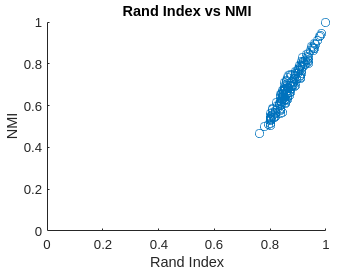

figure;
scatter(rand_index(:),total_nmi(:), 'o')
xlim([0 1])
ylim([0 1])
title("Rand Index vs NMI")
xlabel("Rand Index")
ylabel("NMI")

It is worth noting that both Rand Index and NMI try to find how similar module paritions are to each other with one being each having the same parition. However, it appears that based on this graph often times Rand Index tends to have stronger figures and less over all variation than NMI tends to have. 

**(3.4)** Perform consensus clustering, by iteratively rerunning the Louvain algorithm as above until the partitions converge.

%get consesus structure
consensus = zeros(100, 100);
for i = 1:100
    parition_consensus = (paritions(:, i) == paritions(:, i)');
    consensus = consensus + parition_consensus;
end
consensus = consensus / 100;

%run algorithim on consensus structure with stability criteria
best_nmi = 0;
old_paritions = paritions;
louvain_consensus = zeros(100);

% we want the NMI to be large because that means the current and old parition are similar 
while best_nmi < .999
    %create a new parition
    for i = 1:100
        louvain_consensus(:,i) = community_louvain_with_finetuning(consensus);
    end
    %compute the NMI with respect to the old parition and the new one
    [~, new_nmi]= partition_distance(louvain_consensus, old_paritions);
    %reassign the parition to compare  to the next try
    old_paritions = louvain_consensus;
    best_nmi = min(min(new_nmi));
end

#### 4. Module detection: multiresolution clustering

**(4.1)** Use consensus clustering as above to search for module structure across resolution parameters from 0.5 to 2.5 in 0.05 increments.

%run algorithim on consensus structure with a gamma
gamma = [.5:.05:2.5];
louvain_consensus_gamma = {};
for g = 1:length(gamma)
    louvain_consensus = zeros(100, 100);
    q_score = zeros(1, 100);
    for i = 1:100
        [louvain_consensus(:, i), q_score] = community_louvain_with_finetuning(consensus, gamma(g));
    end
    louvain_consensus_gamma{g} = louvain_consensus;
end

**(4.2)** Plot the number of modules detected for all consensus partitions computed for the previous question.

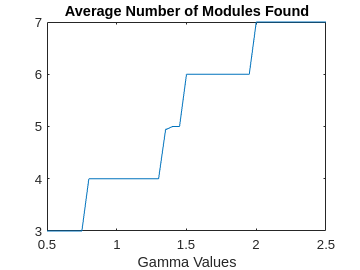

number_of_modules = [];
for i = 1:41
    current_parition = louvain_consensus_gamma{i};
    number_of_modules = [number_of_modules, mean(max(current_parition))];
end
figure;
plot(gamma,number_of_modules)
title("Average Number of Modules Found")
xlabel("Gamma Values")

**(4.3)** Compute and visualize the partition similarity between all pairs of partitions computed for question 1. Define some stability criterion and use it to find a stable partition resolution.

best_nmi = 0;
%iterate over the paritions and calculate the nmi at each resolution
for g = 1:41
    [~, nmi] = partition_distance(louvain_consensus_gamma{g});
    %assign the smallest nmi to nmi to check 
    current_nmi = min(min(nmi));
    if current_nmi > best_nmi %stability is the best nmi 
        best_nmi = current_nmi; %assign the best nmi which is the most stable we can do
        best_gamma = gamma(g);  %assign the gamma associated with that nmi
    end
end

#### 5. Module detection: dynamic module changes

**(5.1)** Divide the original timeseries into 12 equally sized windows.

timeseries = {};
start = 1;
for i = 1:12
    timeseries{i} = data(:,start:i * 100);
    start = start + 100;
end

**(5.2)** For each window, use consensus clustering as above to compute a stable module partition at the default resolution parameter.

timeseries_louvain = {};
for t = 1:12
    %get the window
    data_correlation = corr(timeseries{t}');
    data_correlation = max(data_correlation,0);
    
    %get the inital parition for that window
    k = 100;
    paritions = zeros(length(data_correlation), k);
    q_score = zeros(1, k);    
    for i = 1:k
        [paritions(:, i), q_score] = community_louvain_with_finetuning(data_correlation);
    end

    %get consesus structure
    consensus = zeros(100, 100);
    for i = 1:100
        parition_consensus = (paritions(:, i) == paritions(:, i)');
        consensus = consensus + parition_consensus;
    end
    consensus = consensus / length(data_correlation);
    
    %run algorithim on consensus structure to find a stable parition
    best_nmi = 0;
    while best_nmi < .8 %must share a mutual information of atleast 80%
        louvain_consensus = zeros(100, 100);
        q_score = zeros(1, 100);
        for i = 1:100
            [louvain_consensus(:, i), q_score] = community_louvain_with_finetuning(consensus);
        end
        [~, best_nmi]= partition_distance(louvain_consensus);
        best_nmi = min(min(best_nmi)); %see if we meet criterion in the current cluster       
    end

    timeseries_louvain{t} = louvain_consensus;
end

**(5.3)** Compute the within-module probability matrix across stable partitions at all slices. Average the within-module probability for each node. Use the x, y, z coordinates to appropriately visualize these stabilities on a scatter plot.

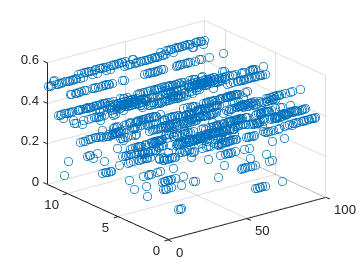

%compute within module probability for each parition
timeseries_consensus = {};
for t = 1:12
    timeseries_paritions = timeseries_louvain{t};
    consensus = zeros(100);
    for i = 1:100
        parition_consensus = (timeseries_paritions(:, i) == timeseries_paritions(:, i)');
        consensus = consensus + parition_consensus;
    end
    consensus = consensus / 100;
    timeseries_consensus{t} = consensus;
end

%average across the nodes within each consensus
mean_consensus = [];
for t = 1:12
    current_mean = mean(timeseries_consensus{t});
    current_timeseries =  ones(100,1) * t;
    current_node = [1:1:100];
    all = [current_mean; current_timeseries'; current_node];
    mean_consensus = [mean_consensus, all];
end

z = mean_consensus(1,:); %make the z the means
y = mean_consensus(2,:); %make the x the time series
x = mean_consensus(3,:); %make the y the node

scatter3(x, y, z);

**Helper Functions**

function [M, Q] = community_louvain_with_finetuning(W, gamma)

if ~exist('gamma', 'var')
    gamma = 1;
end

% initial modularity vector
M = 1:length(W);

% initial modularity values
Q_prev = -inf;
Q = 0;

% while modularity increases
while Q - Q_prev > 1e-5
    
    % run modularity with previous affiliation
    Q_prev = Q;
    [M, Q] = community_louvain(W, gamma, M);
end

end

function vis_network(W)
% function to network matrices and diagrams

figure,
tiledlayout(1, 2, 'padding', 'none')

% visualize network matrix
nexttile;
imagesc(W);
title('network matrix')
axis square;
colorbar;

% visualize network diagram
nexttile;
A = max(W, 0);
for i = 1:height(A)
    [~, ix] = sort(A(i, :), 'descend');
    A(i, ix(6:end)) = 0;
end
A = A + A';

G = graph(A);
plot(G, 'LineWidth', G.Edges.Weight/2)
title('network diagram')
axis square;

end


function vis_modularity(M0, Q0)
% function to visualize community structure

figure,
tiledlayout(1, 2, 'padding','none')

nexttile
[~, NMI] = partition_distance(M0);
imagesc(NMI, [0 1]);
xlabel('partition')
ylabel('partition')
title('normalized mutual information')
axis square; colorbar

nexttile
histogram(Q0)
title('modularity')
axis square

end

function vis_timeseries(T)
% function to visualize timeseries and correlation matrices

figure,
tiledlayout(2, 1)

nexttile
imagesc(T)
xlabel('timepoints')
ylabel('brain regions')
colorbar

nexttile
imagesc(corr(T'), [-0.5 0.5])
xlabel('brain regions')
ylabel('brain regions')
axis square
colorbar
end